## Wczytanie nagrań

files = {
    'data/prawo_1.wav'
    'data/prawo_2.wav'
    'data/prawo_3.wav'
    'data/lewo_1.wav'
    'data/lewo_2.wav'
    'data/lewo_3.wav'
    'data/stop_1.wav'
    'data/stop_2.wav'
    'data/stop_3.wav'
    'data/start_1.wav'
    'data/start_2.wav'
    'data/start_3.wav'
};

labels = [1 1 1 2 2 2 3 3 3 4 4 4];

names = {
    'prawo'
    'lewo'
    'stop'
    'start'
};

% zakładamy takie samo fs dla wszystkich nagrań
[~, fs] = audioread(files{1});

data = {};

for k=1:length(files)
    data{k} = audioread(files{k});
    data{k} = data{k} / max(data{k});
end


### Podział na zbiór treningowy i testowy

train_ids = [1 2 4 5 7 8 10 11];

test_ids = [3 6 9 12];

## Przetwarzanie i normalizacja danych

W tym miejscu następuje przygotowanie danych do dalszej analizy. Zależnie od wybranego sposobu liczenia cech może tutaj następować wyrównanie długości nagrań, normalizacja głośności, wycinanie gragmentów ciszy itp. 

for k=1:length(data)
    data{k} = preprocess(data{k});
end

## Ekstrakcja wektora cech

Dla każdego nagrania należy wyznaczyć jego reprezentację. Powinna ona być kompaktowa, mieć dużo wspólnych cech dla nagrań tego samego słowa oraz dobrze rozróżniać nagrania różnych słów. Powinna być też możliwie niezależna od mówcy (w tym zadaniu nie zależy nam na identyfikacji osób). Przykładowa implementacja wykorzystuje bardzo prostą cechę: moc sygnału w różnych częstotliwościach, bez normalizacji częstotliwości bazowej.

% wyznacz jedną cechę do określenia rozmiaru wektora
% zakładamy stały rozmiar wektora cech
tmp = extract(data{1}, fs);
feats = zeros(length(tmp), length(data));

% wyznaczenie cech dla wszystkich danych
for k=1:length(data)
    feats(:,k) = extract(data{k}, fs);
end

## Trening klasyfikatora

Podstawą treningu są wektory cech i etykiety danych trenujących. Wyjściem powinien być pewien model dostępnych klas. Zależnie od wybranego klasyfikatora może mieć on różną postać. W ramach przykładu przygotowane zostały dwa proste klasyfikatory: najbliższego sąsiada (1-NN) oraz geometryczny. Klasyfikator 1-NN nie potrzebuje żadnego dodatkowego przygotowania danych - zbiór treningowy jest jednocześnie uzwanany za model. W przypadku klasyfikatora geometrycznego dla każdej z klas wyznaczane są uśrednione wektory cech i to one są zwracane jako ostateczny model. 

[model1, labels1] = fit_1nn(feats(:, train_ids), labels(train_ids));
[model2, labels2] = fit_geom(feats(:, train_ids), labels(train_ids));

## Test klasyfikatora 1-NN

Wykorzystując wytrenowane modele i podzbiór testowy można wyznaczyć ich predykcje i określić skuteczność klasyfikacji.

cls1 = predict_1nn(feats(:, test_ids), model1, labels1)

cls1 =      1     2     4     1


Znając oczekiwane etykiety dla klas można wyznaczyć skuteczność (liczbę poprawnych klasyfikacji):

cls_true = labels(test_ids);
acc1 = sum(cls1 == cls_true) / length(cls1)

acc1 = 0.5000

Dokładniejsza analiza błędów może być dokonana przy użyciu macierzy pomyłek:

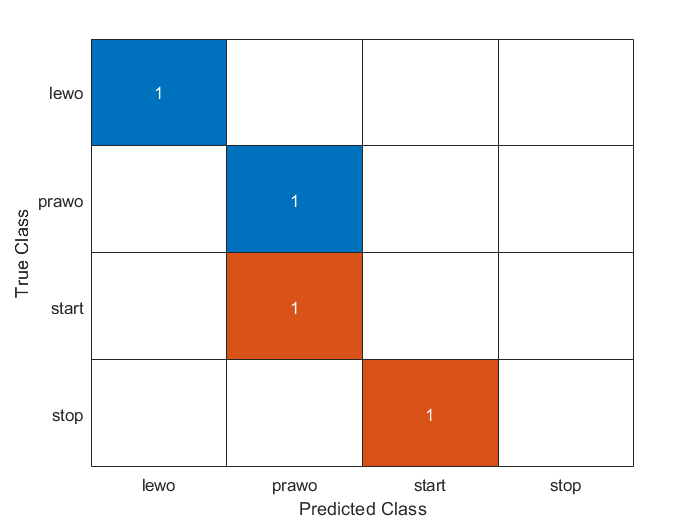

figure;
confusionchart(confusionmat(cls_true, cls1), names)

## Test klasyfikatora geometrycznego

cls2 = predict_geom(feats(:, test_ids), model2, labels2)

cls2 =      1     2     3     1


acc2 = sum(cls2 == cls_true) / length(cls2)

acc2 = 0.7500

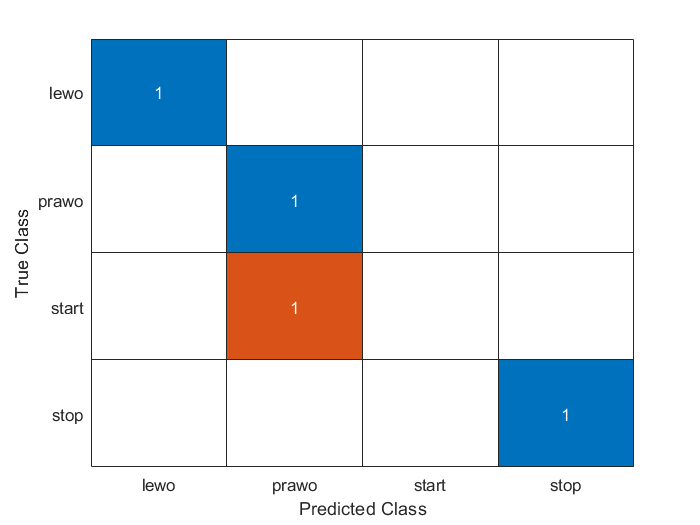

confusionchart(confusionmat(cls_true, cls2), names)

## Detekcja słów kluczowych w strumieniu

Dzieląc długie nagranie na (nakładające się) okna o ustalonej długości możemy każde z nich przepuścić przez wybrany klasyfikator. 

% ważne założenie: nagranie ma takie samo Fs jak dane treningowe
stream = audioread('data/stream.wav');

% zakładana długość i overlap słowa kluczowego (liczba próbek)
len = round(0.8 * fs);
overlap = round(0.1 * fs);

cls = zeros(length(stream), 1);
dst = zeros(length(stream), 1);

for k=1:overlap:length(stream)-len
    r = stream(k:k+len);
    r = preprocess(r, fs);
    f = extract(r, fs);
    [cls(k:k+len), dst(k:k+len)] = predict_1nn(f, model1, labels1);
end

Klasyfikator zawsze daje jakąś odpowiedź, ale przyjmując pewne założenie dotyczące progu odległości możemy wyciąć predykcje niepewne:

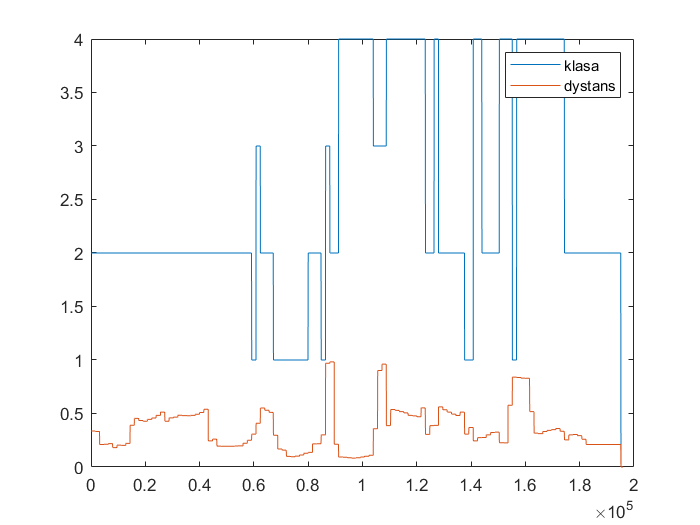

figure; plot(cls); hold on; plot(dst); hold off; legend(["klasa", "dystans"]);

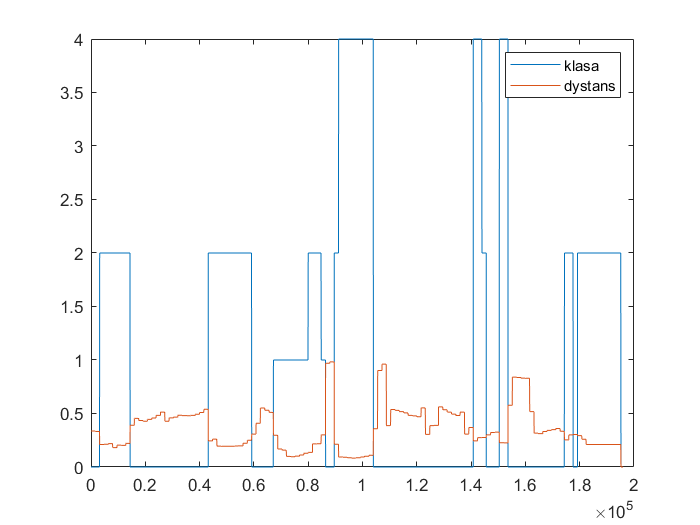

cls_filt = cls;
cls_filt(dst > 0.3) = 0;
figure; plot(cls_filt); hold on; plot(dst); hold off; legend(["klasa", "dystans"]);

## Analiza jakości detekcji

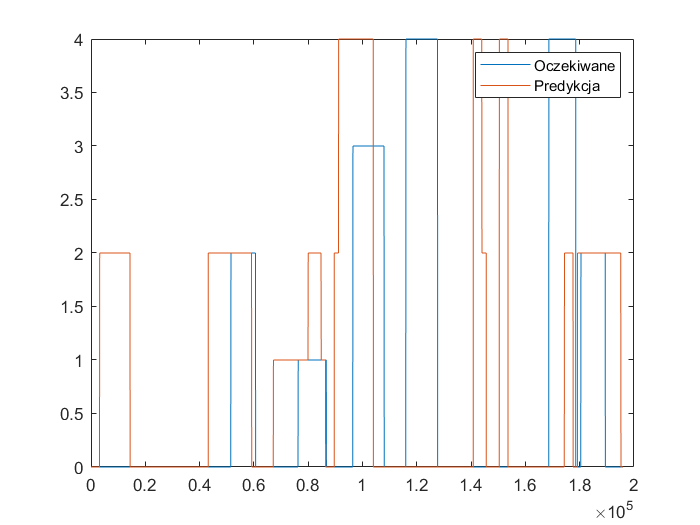

% wczytanie etykiet nagrania testowego
lbls = load('data/labels.txt');

figure; plot(lbls); hold on; plot(cls_filt); legend("Oczekiwane", "Predykcja");

Jakość detekcji można określić na podstawie różnych wskaźników. Jednym z popularnych jest indeks Jaccarda, zwany też IoU (intersection over union). Dla każdej z klas niezależnie wyznaczamy stosunek wszystkich próbek poprawnie sklasyfikowanych (część wspólna) do wszystkich rpóbek oznaczonych jako dana klasa w etykietach oraz predykcji (suma):

acc_1 = sum(lbls == 1 & cls_filt == 1) / sum(lbls == 1 | cls_filt == 1)

acc_1 = 0.2705

Jest też oczywiście do tego gotowa funkcja:

jaccard(cls_filt, lbls)

ans =     0.2705
    0.2978
         0
         0


## Definicje funkcji

### Przetwarzanie wstępne

function y = preprocess(x, fs)
    y = x / max(x);
end

### Ekstrakcja wektora cech

function f = extract(x, fs)
    nfft = 256;
    f = pwelch(x, 1024, 256, nfft, fs);
    f = f / max(f);
end

### Klasyfikator 1-NN

function [model, labels] = fit_1nn(x, y)
    model = x;
    labels = y;
end

function [cls, dst] = predict_1nn(feats, model, labels)
    % wyznacz wszystkie odległości pomiędzy wektorami cech feats a modelem
    dm = pdist2(feats', model', 'cosine');
    
    % znajdź najmniejszą wartość dla każdego wiersza (próbki testowej)
    [dst, min_idx] = min(dm, [], 2);
    
    % określ klasę dla każdej próbki
    cls = labels(min_idx);
end

### Klasyfikator geometryczny

function [model, labels] = fit_geom(x, y)
    cls_num = max(y);
    
    model = zeros(size(x,1), cls_num);
    
    % średnia ze wszystkich kolumn o tej samej etykiecie klasy
    for k = 1:cls_num
        model(:,k) = mean(x(:, y==k), 2);
    end
    
    % po jednej wartości dla każdej klasy
    labels = 1:cls_num;
end

function [cls, dst] = predict_geom(feats, model, labels)
    % wyznacz wszystkie odległości pomiędzy wektorami cech feats a modelem
    dm = pdist2(feats', model', 'cosine');
    
    % znajdź najmniejszą wartość dla każdego wiersza (próbki testowej)
    [dst, min_idx] = min(dm, [], 2);
    
    % określ klasę dla każdej próbki
    cls = labels(min_idx);
end